## Simplified Model

We assume that:

- The tartrazine is homogeneously distributed in the tablets and during the dissolution, it released also homogeneously.

- The bulk concentration is negligible and is equal to zero.

- The surface concentration is always at the solubility limit. See below for explanation.

- During the dissolution, the surface area $A$ of the tablets is unchanged.

- The diffusion is instantly finished and the tartrazine is homogeneously in the solution at any given time.

- The density of the tablets are 1460 $kg/m^3$

The constant we are using is :

    
$$\mu = 8.9\times10^{-4} Pa\cdot s$$


    
$$D_p = 5 mm = 5\times10^{-3} m$$


    
$$D_{AB}  = 4.9\times10^{-10} m^2/s$$


    
$$\rho_f = 1\times10^3 kg/m^3$$



$$c_{a1} = \frac{20 g}{100 mL} / \frac{534.3 g}{1 mol}  = 0.000374321542 mol/mL = 374.32mol/m^3$$


    
$$A = 4\pi r^3 = 4\pi\Big(\frac{D_p}{2}\Big)^2$$


*Since we do not know the flow cell demesion, nor do we want to estimate it, we decide to use the flow speed *$v$* instead of flow rate for the following report.*

mu = 8.9e-4;
Dp = 5e-3;
Dab = 4.9e-10;
rho = 1e3;
ca1 = 374.32;
A = 4*pi*(Dp/2)^2;

## Solubility and Surface Concentrations

We assume that at tablet surface, all tartrazine are dissolved as fast as it can be and it diffused instanly. Since the tablets density is 1460 $kg/m^3$ and is 5%wt, the concentration in the tablets, assuming it is homogeneously distributed, is above 20 $g/dm^3$. Therefore, the surface concentration will always at its max solubility.

## Validation

For this part, $v = 1, 2, 3cm/s$. Therefore $m_A$ can be caluclated based on following set of equations:


$$m_A = A\cdot N_A$$



$$N_A = k_cc_{a1}$$



$$k_c = \frac{N_{sh}D_{AB}}{D_p}$$


$N_{sh} = 2+0.95N_{Re}^{0.5}N_{sc}^{1/3}$ ( $N_{Re}<2000$ )

*The analytical formulas are not displayed due to the complexity and are not required in the report.*

The actual numerical values (in mol/s) are:

v = [1:3]/100;
kc = getkc(v, mu, Dp, Dab, rho);

Na = kc .* ca1;
ma = A .* Na

ma = 	1.0e+-6 *

    0.2561    0.3597    0.4393


## Mass Transfer Rate $m_A$

For different flow speed, the mass trasfer rate curve can be plotted.

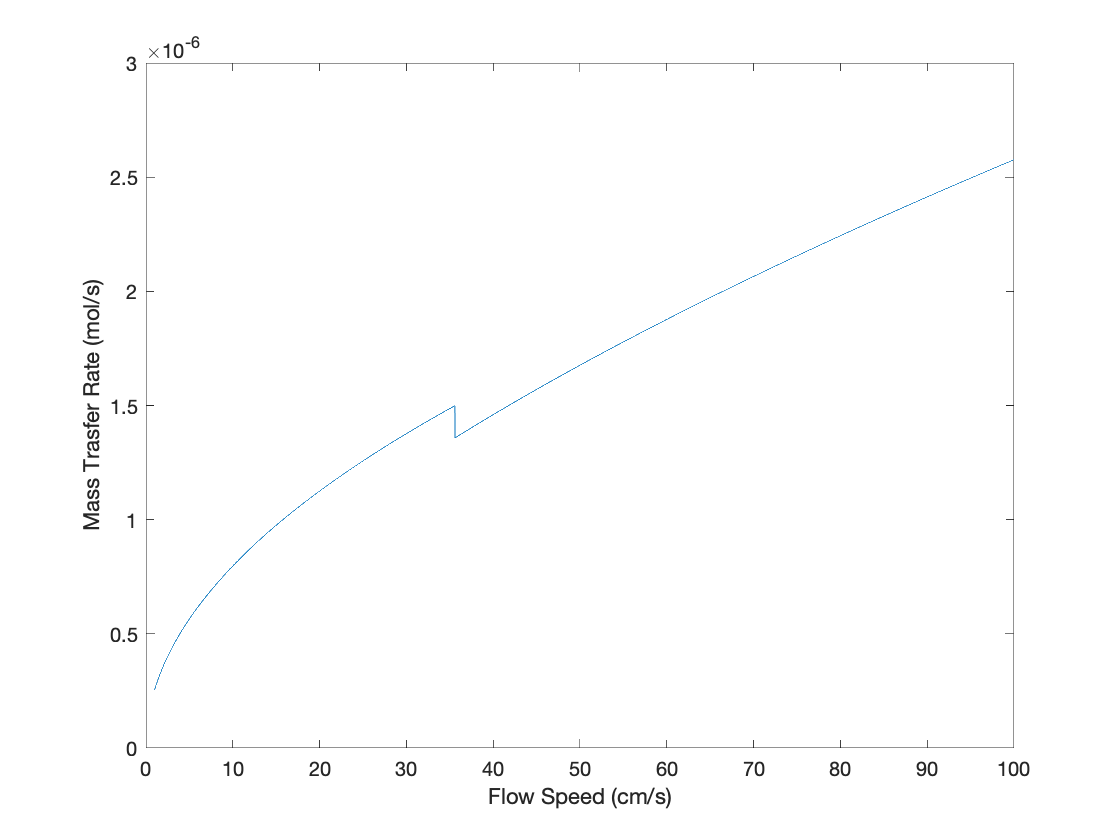

v = [1:0.01:100]/100;
kc = getkc(v, mu, Dp, Dab, rho);

Na = kc .* ca1;
ma = A .* Na;

plot(v*100, ma);
xlabel("Flow Speed (cm/s)");
ylabel("Mass Trasfer Rate (mol/s)");

## Volume Change 

Based on previous assumpsions,if $m_A$ remains unchanged over the process, the volume for different flow speed over time are shown below:

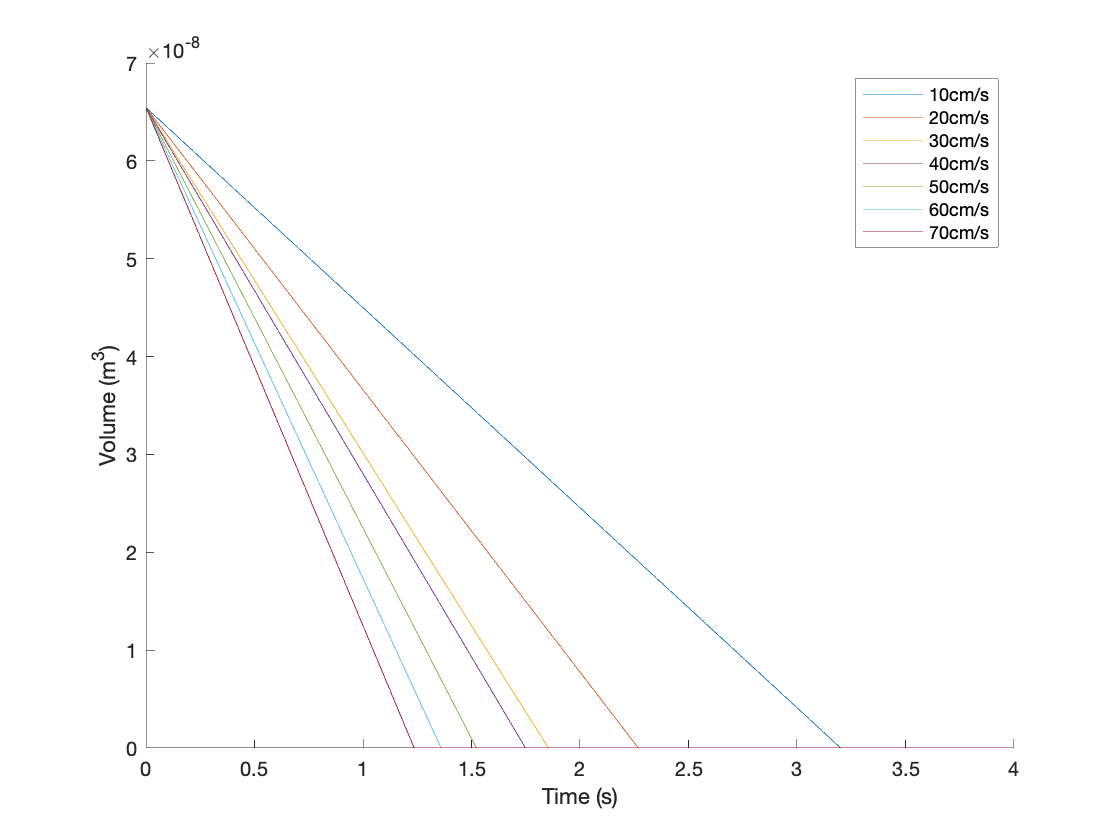

v_all = [10:10:70];
figure
hold on
for v = v_all/100
    kc = getkc(v, mu, Dp, Dab, rho);
    
    Na = kc .* ca1;
    ma = A .* Na;
    
    t = linspace(0,4,1000);
    vol = ma/(534.3/1000)/0.05/1460*t;
    total_vol = (4/3*pi*(Dp/2)^3) - vol;
    total_vol = total_vol.*(total_vol>=0);
    plot(t,total_vol)
end
hold off
xlabel("Time (s)")
ylabel("Volume (m^3)")
legend(strcat(split(int2str(v_all)),"cm/s"))

## Advanced Model

Now we take surface area reduction and volume reduction into consideration:

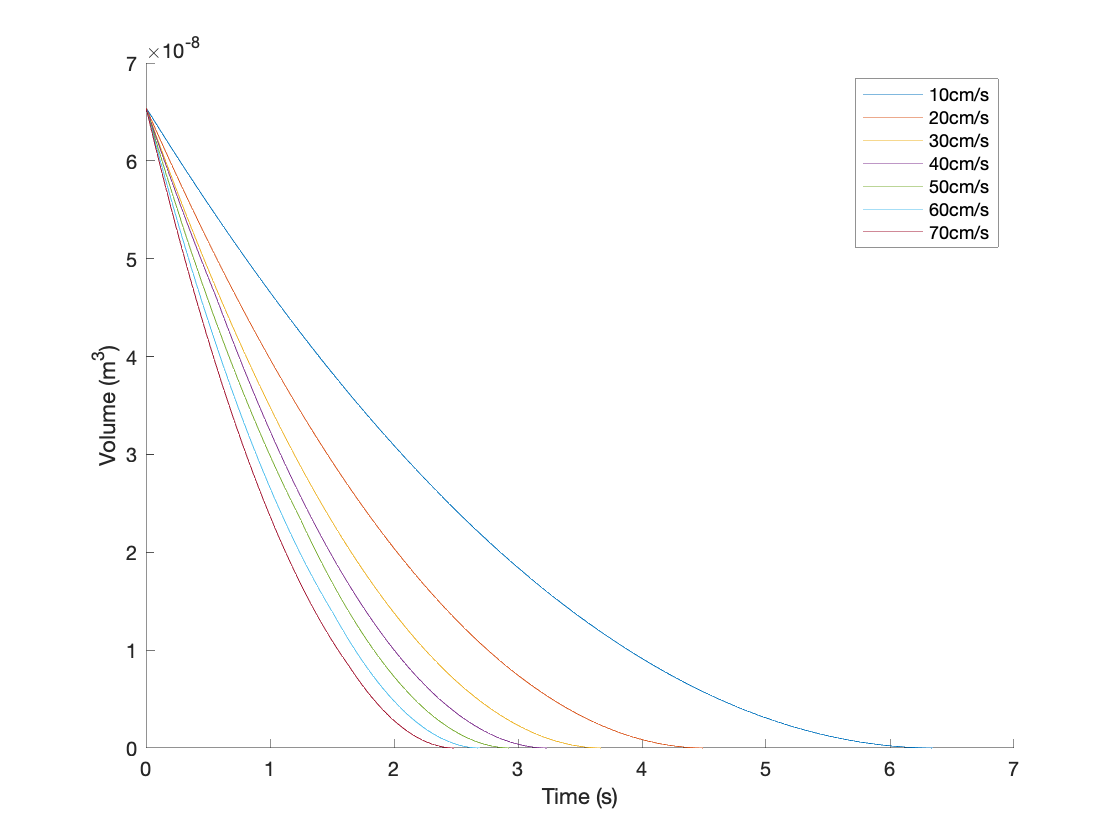

dt = 0.01;

v_all = [10:10:70];
l = strcat(split(int2str(v_all)),"cm/s");
f1 = figure;
hold on
f2 = figure;
hold on
f3 = figure;
hold on
for v = v_all/100 
    % Init
    mu = 8.9e-4;
    Dp = 5e-3;
    Dab = 4.9e-10;
    rho = 1e3;
    ca1 = 374.32;
    total_vol = 4/3*pi*(Dp/2)^3;
    A = 4*pi*(Dp/2)^2;
    v_t = [total_vol];
    A_t = [A];
    Dp_t = [Dp];
    while (total_vol > 0)
        kc = getkc(v, mu, Dp, Dab, rho);
        Na = kc * ca1;
        ma = A * Na;
        dv = ma*dt/(534.3/1000)/0.05/1460;
        total_vol = total_vol - dv;
        total_vol = total_vol*(total_vol>0);
        Dp = (total_vol*3/4/pi)^(1/3)*2;
        A = 4*pi*(Dp/2)^2;
        v_t = [v_t total_vol];
        A_t = [A_t A];
        Dp_t = [Dp_t Dp];
    end
    figure(f1)
    plot([0:dt:dt*length(v_t)-dt],v_t)
    figure(f2)
    plot([0:dt:dt*length(v_t)-dt],A_t)
    figure(f3)
    plot([0:dt:dt*length(v_t)-dt],Dp_t)
end
figure(f1)
hold off
xlabel("Time (s)")
ylabel("Volume (m^3)")
legend(l)

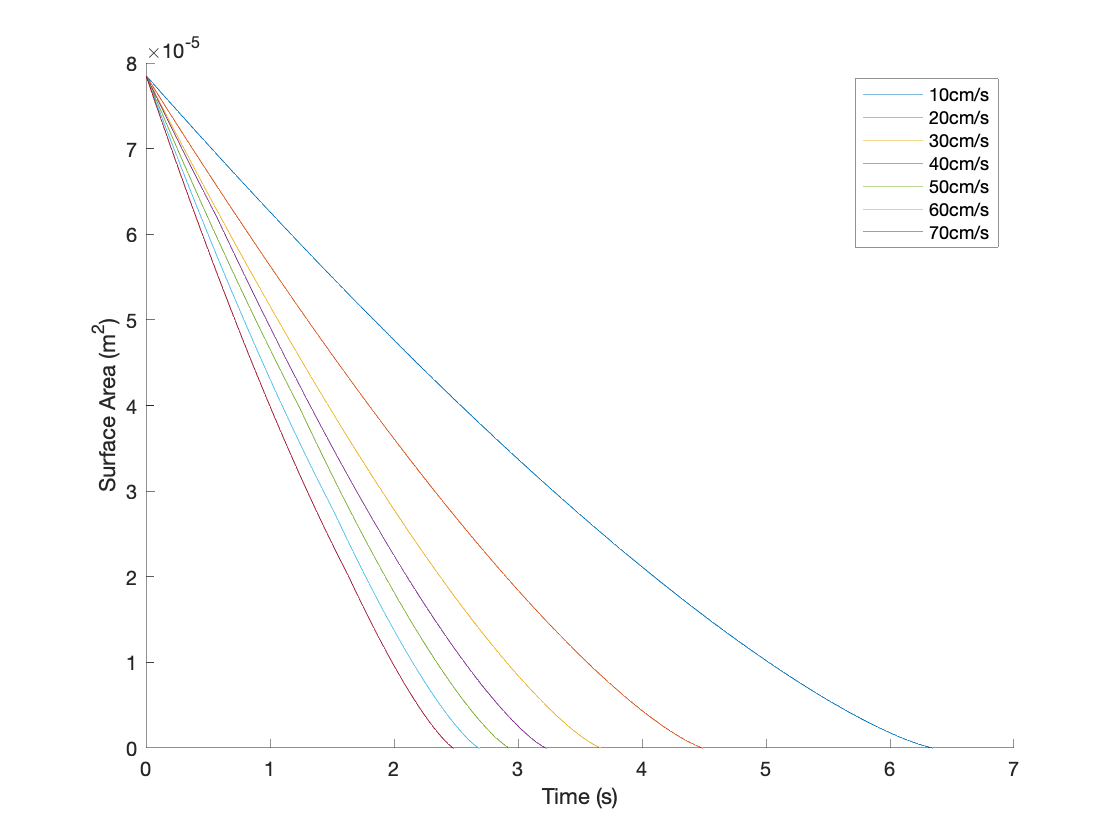


figure(f2)
hold off
xlabel("Time (s)")
ylabel("Surface Area (m^2)")
legend(l)

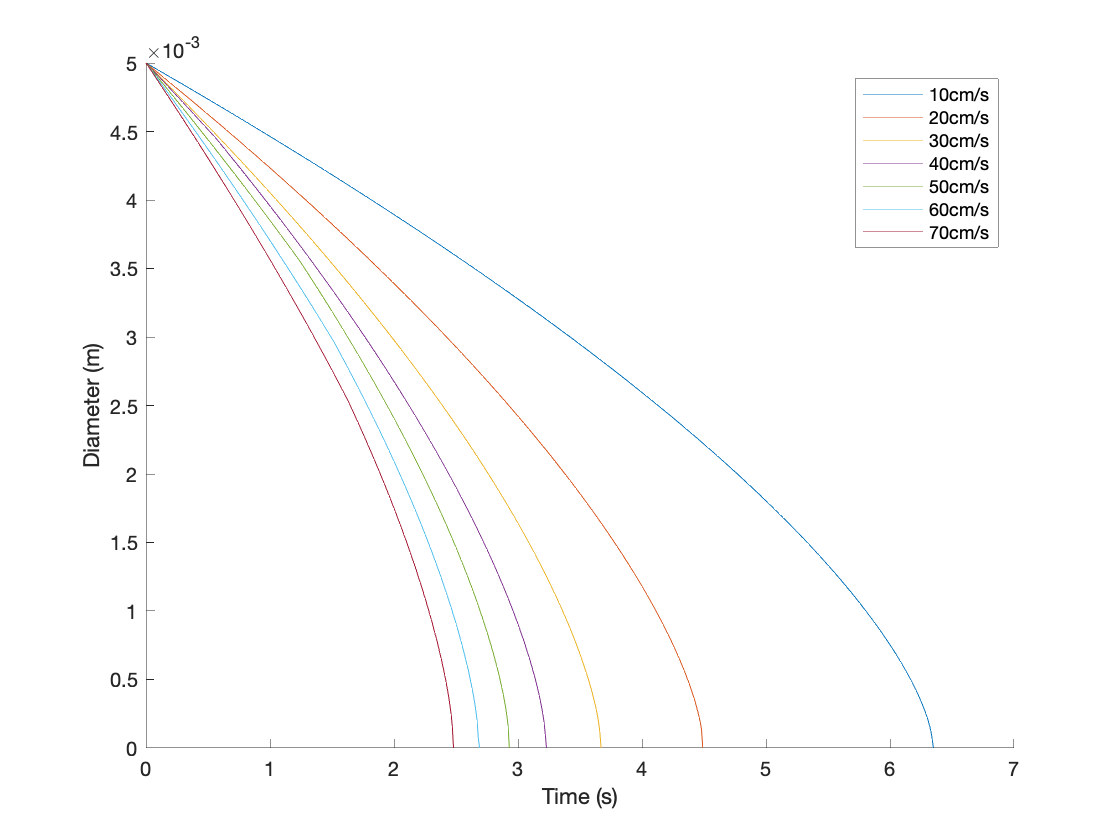


figure(f3)
hold off
xlabel("Time (s)")
ylabel("Diameter (m)")
legend(l)

The detail code (such as the function `getkc`) can be found at the following Git location: [https://github.com/luxwig/CHEM4930_DISSOLUTION](https://github.com/luxwig/CHEM4930_DISSOLUTION)